# Train DDPG Agent to Control Flying Robot

This example shows how to train a deep deterministic policy gradient (DDPG) agent to generate trajectories for a flying robot modeled in Simulink®. For more information on DDPG agents, see  [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_66c8fe60-f58e-4bdb-904a-21d442f0a879).

## Flying Robot Model

The reinforcement learning environment for this example is a flying robot with its initial condition randomized around a ring of radius `15` m. The orientation of the robot is also randomized. The robot has two thrusters mounted on the side of the body that are used to propel and steer the robot. The training goal is to drive the robot from its initial condition to the origin facing east.

Open the model.

mdl = 'rlFlyingRobotEnv';
open_system(mdl)

Set the initial model state variables.

theta0 = 0;
x0 = -15;
y0 = 0;

Define the sample time `Ts` and the simulation duration `Tf`.

Ts = 0.4;
Tf = 30;

For this model:

- The goal orientation is `0` rad (robot facing east).

- The thrust from each actuator is bounded from `-1` to `1` N

- The observations from the environment are the position, orientation (sine and cosine of orientation), velocity, and angular velocity of the robot.

- The reward $r_t$ provided at every time step is


$$r_1 =10\left(\left({x_t }^2 +{y_t }^2 +\theta_t {\;}^2 \right)<0\ldotp 5\right)$$



$$r_2 =-100\left(\left|x_t \right|\ge 20\;\left|\right|\;\left|y_t \right|\ge 20\right)$$



$$r_3 =-\left(0\ldotp 2{\left(R_{t-1} +L_{t-1} \right)}^{2\;} +0\ldotp 3{\left(R_{t-1} -L_{t-1} \right)}^2 +0\ldotp 03{x_t }^2 +0\ldotp 03{y_t }^2 +0\ldotp 02\theta_t {\;}^2 \right)$$



$$r_t =r_1 +r_2 +r_3$$


    where:

- $x_t$ is the position of the robot along the x-axis.

- $y_t$ is the position of the robot along the y-axis.

- $\theta {\;}_t$ is the orientation of the robot.

- $L_{t-1}$ is the control effort from the left thruster.

- $R_{t-1}$ is the control effort from the right thruster.

- $r_1$ is the reward when the robot is close to the goal.

- $r_2$ is the penalty when the robot drives beyond `20 `m in either the x or y direction. The simulation is terminated when $r_2 <0$.

- $r_3$ is a QR penalty that penalizes distance from the goal and control effort.

## Create Integrated Model

To train an agent for the `FlyingRobotEnv` model, use the `createIntegratedEnv` function to automatically generate an integrated model with the RL Agent block that is ready for training.

integratedMdl = 'IntegratedFlyingRobot';
[~,agentBlk,observationInfo,actionInfo] = createIntegratedEnv(mdl,integratedMdl);

## Actions and Observations

Before creating the environment object, specify names for the observation and action specifications, and bound the thrust actions between `-1 `and `1`.

The observation signals for this environment are $\textrm{observation}={\left\lbrack \begin{array}{ccccccc}
x & y & \dot{x}  & \dot{y}  & \sin \left(\theta \;\right) & \cos \left(\theta \right) & \dot{\theta \;} 
\end{array}\right\rbrack }^T$.

numObs = prod(observationInfo.Dimension);
observationInfo.Name = 'observations';

The action signals for this environment are $\textrm{action}={\left\lbrack \begin{array}{cc}
T_R  & T_L 
\end{array}\right\rbrack }^T$ .

numAct = prod(actionInfo.Dimension);
actionInfo.LowerLimit = -ones(numAct,1);
actionInfo.UpperLimit =  ones(numAct,1);
actionInfo.Name = 'thrusts';

## Create Environment Interface

Create an environment interface for the flying robot using the integrated model.

env = rlSimulinkEnv(integratedMdl,agentBlk,observationInfo,actionInfo);

## Reset Function

Create a custom reset function that randomizes the initial position of the robot along a ring of radius `15` m and the initial orientation. For details on the reset function, see `flyingRobotResetFcn`.

env.ResetFcn = @(in) flyingRobotResetFcn(in);

Fix the random generator seed for reproducibility.

rng(0)

## Create DDPG agent

A DDPG agent approximates the long-term reward given observations and actions by using a critic value function representation. To create the critic, first create a deep neural network with two inputs (the observation and action) and one output. For more information on creating a neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

% Specify the number of outputs for the hidden layers.
hiddenLayerSize = 100; 

observationPath = [
    featureInputLayer(numObs,'Normalization','none','Name','observation')
    fullyConnectedLayer(hiddenLayerSize,'Name','fc1')
    reluLayer('Name','relu1')
    fullyConnectedLayer(hiddenLayerSize,'Name','fc2')
    additionLayer(2,'Name','add')
    reluLayer('Name','relu2')
    fullyConnectedLayer(hiddenLayerSize,'Name','fc3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(1,'Name','fc4')];
actionPath = [
    featureInputLayer(numAct,'Normalization','none','Name','action')
    fullyConnectedLayer(hiddenLayerSize,'Name','fc5')];

% Create the layer graph.
criticNetwork = layerGraph(observationPath);
criticNetwork = addLayers(criticNetwork,actionPath);

% Connect actionPath to observationPath.
criticNetwork = connectLayers(criticNetwork,'fc5','add/in2');

% Create dlnetwork from layer graph
criticNetwork = dlnetwork(criticNetwork);

Specify options for the critic using `rlOptimizerOptions`.

criticOptions = rlOptimizerOptions('LearnRate',1e-03,'GradientThreshold',1);

Create the critic representation using the specified neural network and options. You must also specify the action and observation specification for the critic. For more information, see [`rlQValueFunction`](docid:rl_ref#mw_e6e7abac-0a33-423b-8473-1409879db701).

critic = rlQValueFunction(criticNetwork,observationInfo,actionInfo,...
    'ObservationInputNames','observation','ActionInputNames','action');
critic.UseDevice = 'gpu';

A DDPG agent decides which action to take given observations by using an actor representation. To create the actor, first create a deep neural network with one input (the observation) and one output (the action).

Construct the actor similarly to the critic. For more information, see [`rlContinuousDeterministicActor`](docid:rl_ref#mw_c2909424-90f4-4a52-803b-73310483e6c3).

actorNetwork = [
    featureInputLayer(numObs,'Normalization','none','Name','observation')
    fullyConnectedLayer(hiddenLayerSize,'Name','fc1')
    reluLayer('Name','relu1')
    fullyConnectedLayer(hiddenLayerSize,'Name','fc2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(hiddenLayerSize,'Name','fc3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(numAct,'Name','fc4')
    tanhLayer('Name','tanh1')];
actorNetwork = dlnetwork(actorNetwork);

actorOptions = rlOptimizerOptions('LearnRate',1e-04,'GradientThreshold',1);

actor = rlContinuousDeterministicActor(actorNetwork,observationInfo,actionInfo);
actor.UseDevice = 'gpu';

To create the DDPG agent, first specify the DDPG agent options using [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

agentOptions = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'ActorOptimizerOptions',actorOptions,...
    'CriticOptimizerOptions',criticOptions,...
    'ExperienceBufferLength',1e6 ,...
    'MiniBatchSize',256);
agentOptions.NoiseOptions.Variance = 1e-1;
agentOptions.NoiseOptions.VarianceDecayRate = 1e-6;

Then, create the agent using the specified actor representation, critic representation, and agent options. For more information, see [`rlDDPGAgent`](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor,critic,agentOptions);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training for at most `20000` episodes, with each episode lasting at most `ceil(Tf/Ts)` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than `415` over 10 consecutive episodes. At this point, the agent can drive the flying robot to the goal position.

- Save a copy of the agent for each episode where the cumulative reward is greater than `415`.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 20000;
maxsteps = ceil(Tf/Ts);
trainingOptions = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes,...
    'MaxStepsPerEpisode',maxsteps,...
    'StopOnError',"on",...
    'Verbose',false,...
    'Plots',"training-progress",...
    'StopTrainingCriteria',"AverageReward",...
    'StopTrainingValue',415,...
    'ScoreAveragingWindowLength',10,...
    'SaveAgentCriteria',"EpisodeReward",...
    'SaveAgentValue',415); 

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally intensive process that takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

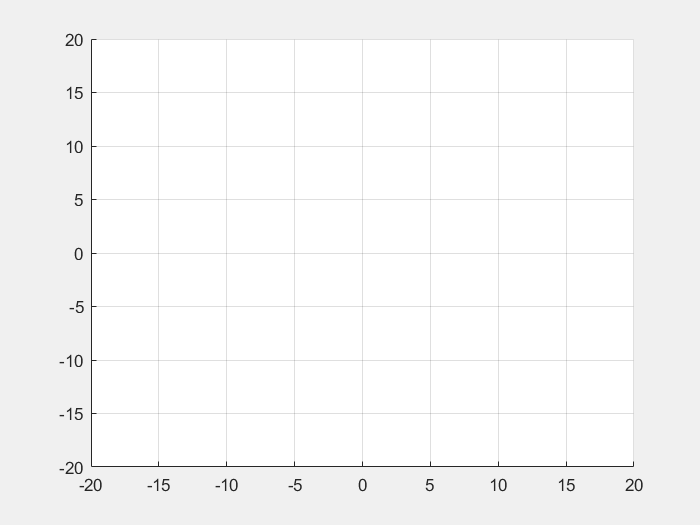

doTraining = true;
if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainingOptions);
    save(['training/training-', char(datetime('yesterday'))], 'trainingStats', 'trainingOptions', 'agent', 'env')
else
    % Load the pretrained agent for the example.
    load('FlyingRobotDDPG.mat','agent')       
end

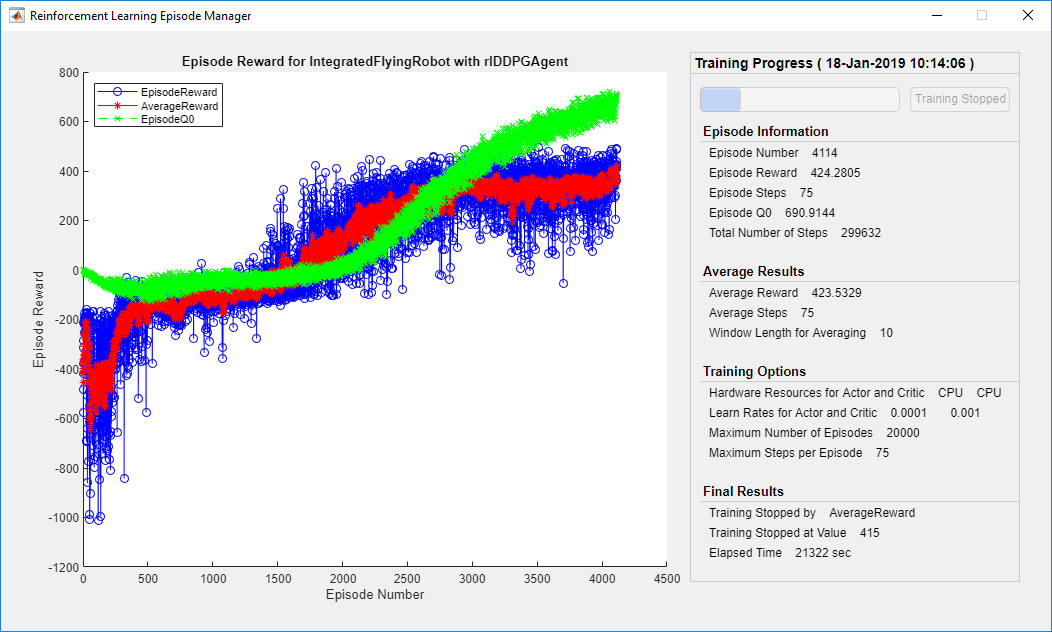

## Simulate DDPG Agent

To validate the performance of the trained agent, simulate the agent within the environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

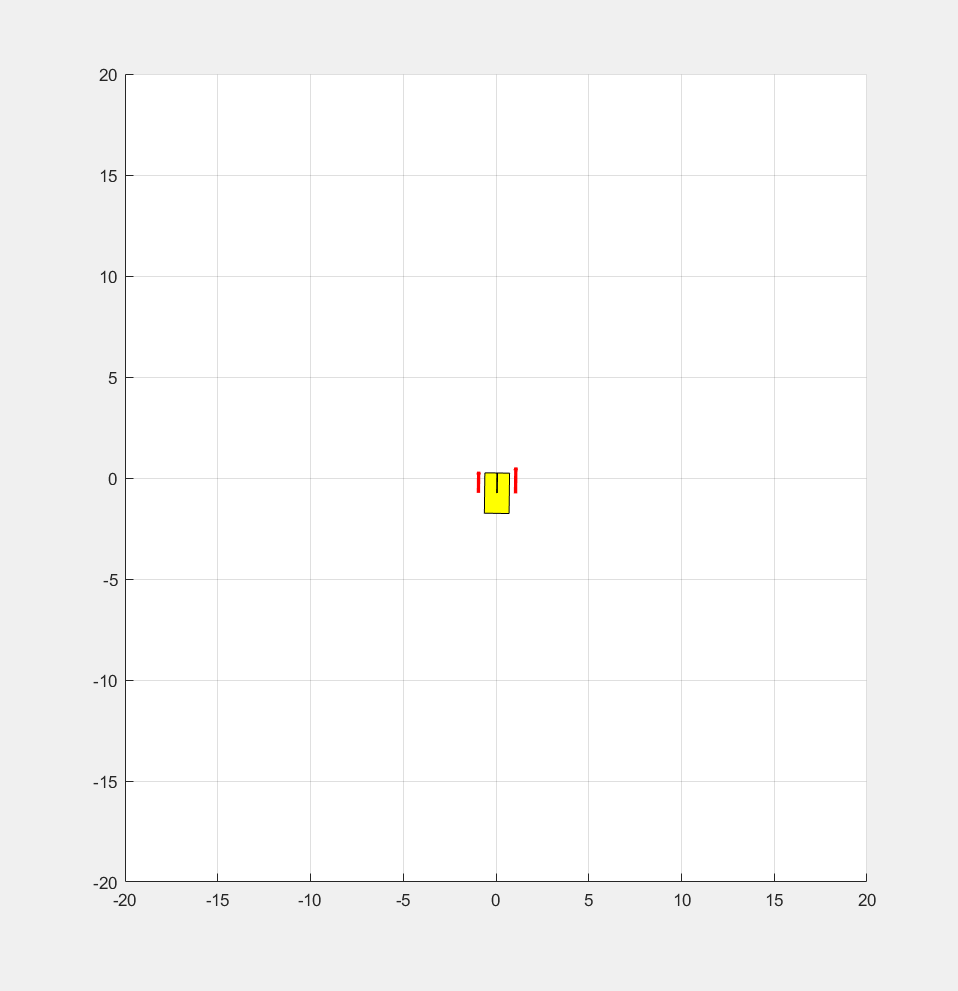

maxsteps=75;
simOptions = rlSimulationOptions('MaxSteps',maxsteps);

experience = sim(env,agent,simOptions);

*Copyright 2018 The MathWorks, Inc.*